# **PRACTICE 2 - OPTIMIZATION TECHNIQUES**

**Andrés Herencia y Antonio Fernández**

**MUTECI 2023-2024**

## Exercise 1

Given the data from the text file titled 'isomerizacion.txt,' determine the parameters that fit the model:


$$y={\frac{\theta_{1}\theta_{2}(x_{2}-x_{3})/1.632}{1+\theta_{2}x_{1}+\theta_{3}x_{2}+\theta_{4}x_{3}}} $$


Request: 

a. Linearize the model and obtain an initial estimate. 

b. With the previous initial estimate, solve the non-linear regression problem by minimizing the squared error.

### Solution

clc
cd('C:\Users\andre\Documents\UNIVERSIDAD\MUTECI\BLOQUE 2\TOPT\lab\P2\')
[x1,x2,x3,y]=textread('isomerizacion.txt','%f %f %f %f','headerlines',8);

#### a) Linearize the model and obtain an initial estimate. 

With $y^{\prime}={\frac{1}{y}}(x_{2}-x_{3}) $ we can operate to achieve this expression: 

  
$$y^{\prime}=(x_{2}-x_{3}){\frac{1+\theta_{2}x_{1}+\theta_{3}x_{2}+\theta_{4}x_{3}}{\theta_{1}\theta_{2}(x_{2}-x_{3})/1.632}}=
\\
= {\frac{1.632}{\theta_{1}\theta_{2}}}(1+\theta_{2}x_{1}+\theta_{3}x_{2}+\theta_{4}x_{3})=
\\
=\beta_{0}+\beta_{1}x_{1}+\beta_{2}x_{2}+\beta_{3}x_{3}$$


Where: $\theta_{1}={\frac{1.632}{\beta_{1}}} $, $\theta_{2}={\frac{\beta_{1}}{\beta_{0}}} $, $\theta_{3}={\frac{\beta_{2}}{\beta_{0}}} $, $\theta_{4}={\frac{\beta_{3}}{\beta_{0}}} $.

X1 = [ones(length(x1),1),x1,x2,x3];
Y1 = [(x2-x3)./y];
beta = inv(X1.'*X1)*X1.'*Y1

beta =    -5.3459
    0.0396
    0.1798
   -0.3108


O(1)=1.632/beta(2);
O(2)=beta(2)/beta(1);
O(3)=beta(3)/beta(1);
O(4)=beta(4)/beta(1);
display(O)

O =    41.1949   -0.0074   -0.0336    0.0581


#### b) With the previous initial estimate, solve the non-linear regression problem by minimizing the squared error.

f = @(x1,x2,x3,y,E) sum((y - (((x2 - x3)./1.632).*(E(1).*E(2)))./(1 + E(2).*x1 + E(3).*x2 + E(4).*x3)).^2);
myfunc = @(E) f(x1,x2,x3,y,E);
[beta_opt, fval, exitflag, output] = fminsearch(myfunc,O)

beta_opt =     4.7969   -0.0071   -0.0059    0.0200


fval = 210.4719

exitflag = 1

output = struct with fields:
    iterations: 241
     funcCount: 409
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


We can check that since the problem is non-linear, is very sensitive to the initial conditions and the optimization method, so, we can not interpretate the solution with ease.

[beta_opt2, fval2, exitflag2, output2] = fminunc(myfunc,O)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


beta_opt2 =    40.1275   -9.7344  -11.7309   -6.8991


fval2 = 16.1631

exitflag2 = 1

output2 = struct with fields:
       iterations: 66
        funcCount: 350
         stepsize: 1.5932
     lssteplength: 1
    firstorderopt: 0.5222
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 6.264512e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


If we want to minimize the quadratic sum of errors, we have to use this method, because the fval parameter is the lowest.

[beta_opt3, fval3, exitflag3, output3] = fminsearch(myfunc,[1,1,1,1])

beta_opt3 =    34.5426   22.5617   21.0227   11.2278


fval3 = 15.2723

exitflag3 = 1

output3 = struct with fields:
    iterations: 316
     funcCount: 545
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


[beta_opt4, fval4, exitflag4, output4] = fminunc(myfunc,[1,1,1,1])


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



beta_opt4 =    34.8978    0.3111    0.2917    0.1643


fval4 = 15.2570

exitflag4 = 0

output4 = struct with fields:
       iterations: 47
        funcCount: 400
         stepsize: 0.1672
     lssteplength: 0.0477
    firstorderopt: 8.3635
        algorithm: 'quasi-newton'
          message: 'Solver stopped prematurely.↵↵fminunc stopped because it exceeded the function evaluation limit,↵options.MaxFunctionEvaluations = 4.000000e+02.'


## Exercise 2

Given the data in the following table:

clc
x = [4.5, 5.0, 5.1, 5.3, 6.2, 7.1]'

x =     4.5000
    5.0000
    5.1000
    5.3000
    6.2000
    7.1000


y = [5.0, 3.8, 4.9, 3.7, 3.6, 15.0]'

y =     5.0000
    3.8000
    4.9000
    3.7000
    3.6000
   15.0000


Determine the regression line $Y=\alpha +\beta X$ when the criterion to be minimezed is:

a. The sum of the squared error, being$\epsilon_i =y_i -\alpha -\beta x_i$ the error of the i-th observation `i=1,2,...,6`.

b. The sum of the absolute value of the errors.

c. The maximum absolute value of the errors.

Solve the three problems with Matlab and represent the three regression lines for illustrate the differences.

### Solution

#### Simple Regression Line and Original Data

X = [ones(length(x),1),x]

X =     1.0000    4.5000
    1.0000    5.0000
    1.0000    5.1000
    1.0000    5.3000
    1.0000    6.2000
    1.0000    7.1000


b = regress(y,X)

b =   -13.3585
    3.4985


Y = b(1) + b(2)*x

Y =     2.3849
    4.1341
    4.4840
    5.1837
    8.3323
   11.4810


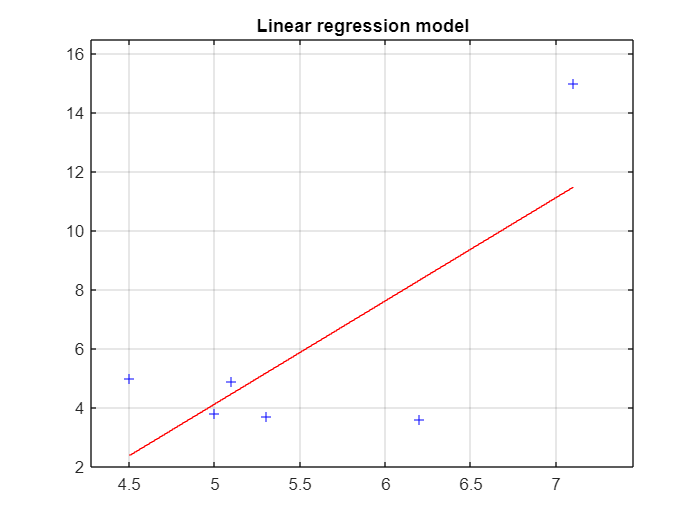

plot(x,y,'b+',x,Y,'r-')
xlim([0.95*min(x),1.05*max(x)])
ylim([2,max(y)*1.1])
title('Linear regression model')
grid on

#### a) The sum of the squared error

Firstly, we define an anonymous function with the unconstrained optimization problem we are trying to solve. We set the parameters that are not objects of the problem by overriding them in a new function. Finally, we solve the optimization problem by defining a pair of initial values as a starting point.

f = @(x,y,beta) sum((y - beta(1) - beta(2).*x).^2)

f = function_handle with value:
    @(x,y,beta)sum((y-beta(1)-beta(2).*x).^2)


myfunc = @(beta) f(x,y,beta)

myfunc = function_handle with value:
    @(beta)f(x,y,beta)


It can be resolved with two different methods natively in MATLAB: `fminunc` and `fminsearch`. We will get the same result.

fminunc(myfunc,[0,0]) % using a gradient boot search method


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans =   -13.3585    3.4985


bopt1 = fminsearch(myfunc,[0,0]) % using derivative-free method

bopt1 =   -13.3585    3.4985


We have obtained the following values:


$$\begin{array}{l}
\alpha =-13\ldotp 3585\\
\beta =3\ldotp 4985
\end{array}$$


#### b) The sum of the absolute value of the errors.

f2 = @(x,y,beta) sum(abs((y - beta(1) - beta(2).*x)))

f2 = function_handle with value:
    @(x,y,beta)sum(abs((y-beta(1)-beta(2).*x)))


myfunc2 = @(beta) f2(x,y,beta)

myfunc2 = function_handle with value:
    @(beta)f2(x,y,beta)


bopt2 = fminsearch(myfunc2,[0,0])

bopt2 =   -22.8665    5.3333


With this method, we have obtained:


$$\begin{array}{l}
\alpha =-22\ldotp 8665\\
\beta =5\ldotp 3333
\end{array}$$


**Using the linear programming method**

*See in the appendix the general structure of a LP problem.*

The optimization problem can be defined as


$$\min_{\alpha,\beta} \sum_{i}^{n} |\epsilon_i |$$


Being


$$\epsilon_i =y_i -{\hat{y} }_i =y_i -\alpha -\beta x_i$$


Since we want to formulate it as a linear programming problem, we have to make a change of variable to leave it in linear terms. This implies that we have to define two new constraints:


$$u_i \le \;|\epsilon_i |=\left\lbrace \begin{array}{ll}
u_i =\left(y_i -{\hat{y} }_i \right)=y_i -\alpha -\beta x_i \le \epsilon_i  & i=1,\ldots,n\\
u_i ={-\epsilon }_i =-\left(y_i -{\hat{y} }_i \right)=-\left(y_i -\alpha -\beta x_i \right)\ge -\epsilon_i  & i=1,\ldots,n
\end{array}\right.$$


With the condition that the absolute value is always positive, our LP problem is:


$$\min_{u_{1}, \dots ,u_n,\alpha, \beta} \sum_{i}^{n} u_i
\\
\textnormal{s. to}
\\
i) -u_i-\alpha-\beta x_i \leq-y_i, \quad   \forall i=1,...,n
\\
ii) -u_i+\alpha+\beta x_i \leq y_i, \quad   \forall i=1,...,n
\\
iii) \; u_i \geq 0$$


In our concrete case, $n=6$. 

Therefore, we have 8 decision variables ($u_1 ,u_2 ,u_3 ,u_4 ,u_5 ,u_6 ,\alpha ,\beta$), 12 inequations, and an inferior bound for each $u_i$. 

n = length(x)

n = 6

u = (-1)*diag(ones(n,1));
Aub = zeros(12,8);
for i = 1:n
    Aub(i,:) = [u(i,:),-1,-x(i)];
    Aub(6+i,:) = [u(i,:),1,x(i)];
end
Aub

Aub =    -1.0000         0         0         0         0         0   -1.0000   -4.5000
         0   -1.0000         0         0         0         0   -1.0000   -5.0000
         0         0   -1.0000         0         0         0   -1.0000   -5.1000
         0         0         0   -1.0000         0         0   -1.0000   -5.3000
         0         0         0         0   -1.0000         0   -1.0000   -6.2000
         0         0         0         0         0   -1.0000   -1.0000   -7.1000
   -1.0000         0         0         0         0         0    1.0000    4.5000
         0   -1.0000         0         0         0         0    1.0000    5.0000
         0         0   -1.0000         0         0         0    1.0000    5.1000
         0         0         0   -1.0000         0         0    1.0000    5.3000


b = [-y;y]

b =    -5.0000
   -3.8000
   -4.9000
   -3.7000
   -3.6000
  -15.0000
    5.0000
    3.8000
    4.9000
    3.7000


c = [ones(1,n),[0,0]]

c =      1     1     1     1     1     1     0     0


lin_pr = linprog(c,Aub,b);

Optimal solution found.



bopt2lin = lin_pr(end-1:end)

bopt2lin =   -22.8667
    5.3333


Solving as an LP problem, we have obtained the following values:


$$\begin{array}{l}
\alpha =-22\ldotp 8667\\
\beta =5\ldotp 3333
\end{array}$$


#### c) The maximum of the absolute values of the errors.

f3 = @(x,y,beta) max(abs((y - beta(1) - beta(2).*x)))

f3 = function_handle with value:
    @(x,y,beta)max(abs((y-beta(1)-beta(2).*x)))


myfunc3 = @(beta) f3(x,y,beta)

myfunc3 = function_handle with value:
    @(beta)f3(x,y,beta)


bopt3 = fminsearch(myfunc3,[0,0])

bopt3 =   -16.2769    3.8462


Obtaining:


$$\begin{array}{l}
\alpha =-16\ldotp 2769\\
\beta =3\ldotp 8462
\end{array}$$


#### Plotting the solutions

reg1 = bopt1(1) + bopt1(2)*x;
reg2 = bopt2(1) + bopt2(2)*x;
reg3 = bopt3(1) + bopt3(2)*x;


$$\begin{cases}
  y_1 = -13.36 + 3.50x \\
  y_2 = -22.87 + 5.33x \\
  y_3 = -16.28 + 3.85x
\end{cases}$$


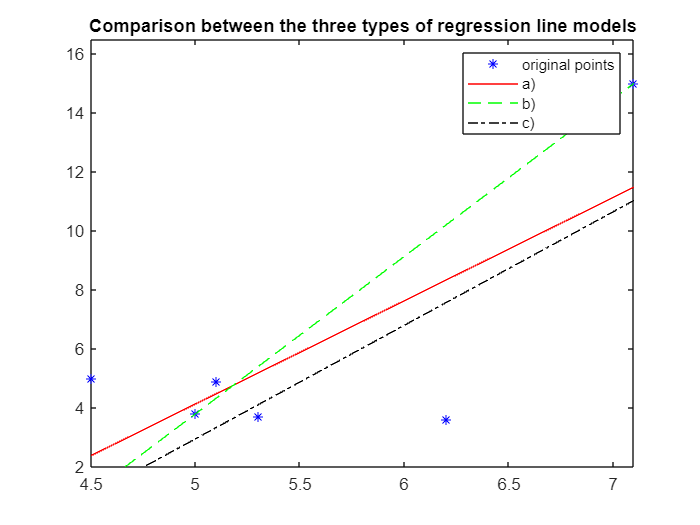

plot(x,y,'b*',x,reg1,'-r',x,reg2,'--g',x,reg3,'-.k')
legend('original points','a)','b)','c)')
xlim([min(x),max(x)])
ylim([2,max(y)*1.1])
title('Comparison between the three types of regression line models')

We can observe that the regression lines are strongly influenced by a point that could be considered an outlier. Depending on the optimization method, the influence of this point is lower or higher. The other points are much nearer; if we had analyzed only those points, the regression line would have been a less pronounced slope.

## Appendix

### Linear Programming Problem structure